#### Shepp–Logan phantom

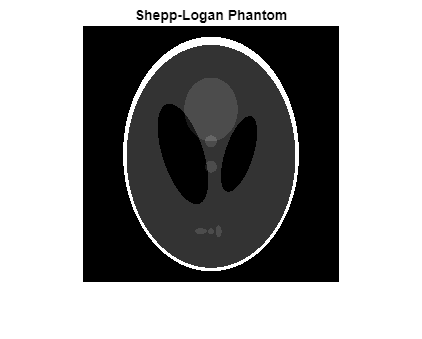

P = phantom(256);
imshow(P, []);
title('Shepp-Logan Phantom');

#### Brain Angiograph

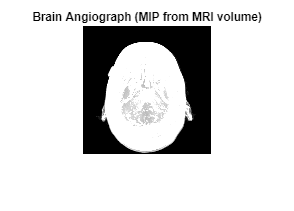

% Load built-in MRI volume
load mri
D = squeeze(D); % remove singleton dimension

% Convert to double and normalize
D = double(D);
D = D / max(D(:));

% Create a max-intensity projection (MIP) along one axis
brain_angiograph = max(D, [], 3);

imshow(brain_angiograph, []);
title('Brain Angiograph (MIP from MRI volume)');